# **ELIPSE FITTING EXAMPLES**

### **Global Variables**

% fundamental frecuency
f = 50; 
w = 2*pi*f;

% Line to neutral amplitud
A = 400; 

% Signal cycles count
nc = 5;

% Offset angle
d = [0, 2*pi/3, 4*pi/3];

% Sampled time
SignalLenght = 10000;
t = 0:(1/SignalLenght):(nc/f - 1/SignalLenght); 
nt = length(t);

% Sampling rate in samples/cycle
fs = nt/nc;

## Example 1: Signal with Harmonics

a = ElectricalSignals("harmonic", A, f, d(1), "alphan", [0.15, 0.09, 0.1, 0.06]);
b = ElectricalSignals("harmonic", A, f, d(2), "alphan", 0.05);
c = ElectricalSignals("harmonic", A, f, d(3), "alphan", [0.1, 0.15, 0.07]);

aDt = diff(a);
bDt = diff(b);
cDt = diff(c);

a = eval(subs(a));
b = eval(subs(b));
c = eval(subs(c));

aDt = eval(subs(aDt));
bDt = eval(subs(bDt));
cDt = eval(subs(cDt));

## Example 2: Signal with Oscillatory Transient

a = ElectricalSignals("transient_osc", A, f, d(1),"beta", 0.4, "theta", pi/3, "t1", 0.2*nc/f, "t2", 0.4*nc/f);
b = ElectricalSignals("harmonic", A, f, d(2), "alphan", [0.09, 0.05]);
c = ElectricalSignals("pure", A, f, d(3));

aDt = diff(a);
bDt = diff(b);
cDt = diff(c);

a = eval(subs(a));
b = eval(subs(b));
c = eval(subs(c));

aDt = eval(subs(aDt));
bDt = eval(subs(bDt));
cDt = eval(subs(cDt));

## Example 3: Signal with Interruption

a = ElectricalSignals("harmonic", A, f, d(1), "alphan", [0.09, 0.05]);
b = ElectricalSignals("interrupt", A, f, d(2), "ro", 0.9, "t1",t(end)*0.4, "t2",t(end)*0.65);
c = ElectricalSignals("pure", A, f, d(3));

aDt = diff(a);
bDt = diff(b);
cDt = diff(c);

a = eval(subs(a));
b = eval(subs(b));
c = eval(subs(c));

aDt = eval(subs(aDt));
bDt = eval(subs(bDt));
cDt = eval(subs(cDt));

## Example 4: Signal with Sags

a = ElectricalSignals("sag", A, f, d(1), "alpha", 0.8, "t1",t(end)*0.35, "t2",t(end)*0.65);
b = ElectricalSignals("sag", A, f, d(2), "alpha", 0.7, "t1",t(end)*0.35, "t2",t(end)*0.65);
c = ElectricalSignals("sag", A, f, d(3), "alpha", 0.6, "t1",t(end)*0.35, "t2",t(end)*0.65);

aDt = diff(a);
bDt = diff(b);
cDt = diff(c);

a = eval(subs(a));
b = eval(subs(b));
c = eval(subs(c));

aDt = eval(subs(aDt));
bDt = eval(subs(bDt));
cDt = eval(subs(cDt));

## Example 4: Signal with Ocilation Swell

a = ElectricalSignals("swell_osc_transient", A, f, d(1), "beta", 0.5, "fn", 400, "theta", pi/2, "tau", 0.01, "t1",t(end)*0.35, "t2",t(end)*0.4, "t11",t(end)*0.35*1.02, "t22",t(end)*0.35*0.98);
b = ElectricalSignals("swell_osc_transient", A, f, d(2), "beta", 0.3, "fn", 300, "theta", pi/3, "tau", 0.015, "t1",t(end)*0.35, "t2",t(end)*0.4, "t11",t(end)*0.35*1.02, "t22",t(end)*0.35*0.98);
c = ElectricalSignals("swell_osc_transient", A, f, d(3), "beta", 0.3, "fn", 300, "theta", pi/4, "tau", 0.012, "t1",t(end)*0.35, "t2",t(end)*0.4, "t11",t(end)*0.35*1.02, "t22",t(end)*0.35*0.98); 

aDt = diff(a);
bDt = diff(b);
cDt = diff(c);

a = eval(subs(a));
b = eval(subs(b));
c = eval(subs(c));

aDt = eval(subs(aDt));
bDt = eval(subs(bDt));
cDt = eval(subs(cDt));

## Example 5: Signal out of phase 

a = ElectricalSignals("pure", A, f, d(1));
b = ElectricalSignals("pure", A, f, d(2) - pi/5);
c = ElectricalSignals("pure", A, f, d(3) + pi/10);

aDt = diff(a);
bDt = diff(b);
cDt = diff(c);

a = eval(subs(a));
b = eval(subs(b));
c = eval(subs(c));

aDt = eval(subs(aDt));
bDt = eval(subs(bDt));
cDt = eval(subs(cDt));

## Example 6: Dataset

%load("DatasetThreePSignal.mat")

class = randi([1 29])

class = 5

sample = randi([1 length(dataset{1}(1,1,:))]);
dt = 1/fs;

a = dataset{1}(class,:,sample);
b = dataset{2}(class,:,sample);
c = dataset{3}(class,:,sample);

aDt = diff(a)/dt;
aDt(end + 1) = aDt(end); 
bDt = diff(b)/dt;
bDt(end + 1) = bDt(end); 
cDt = diff(c)/dt;
cDt(end + 1) = cDt(end); 

### Calculations

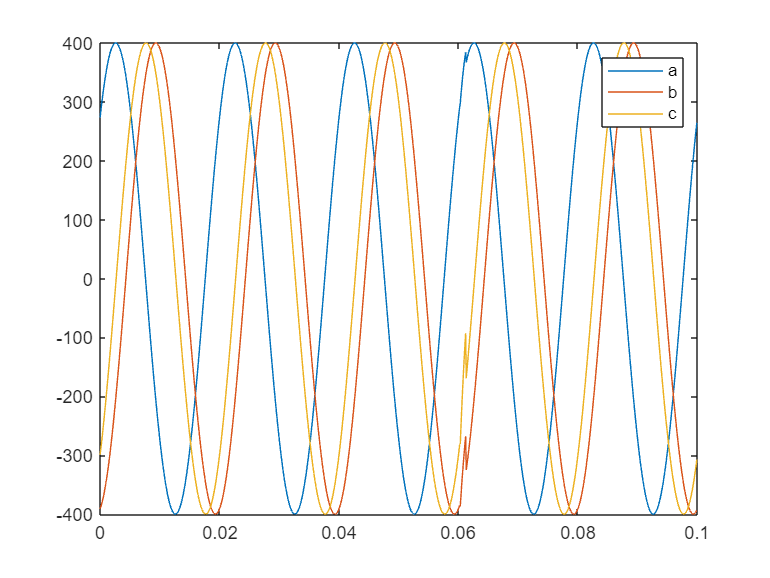

signal_o = [a; b; c];

figure; plot(t,a); hold on; plot(t,b); plot(t,c); hold off; legend("a","b","c")

### **Global Optimization Algorithm**

% We can use PCA for selecting 2 basis vectors for plane of projection
% Make sure signal is nearly centered at the origin
dataCenter = mean(signal_o, 2)

dataCenter =     0.1214
    0.3496
    0.4750


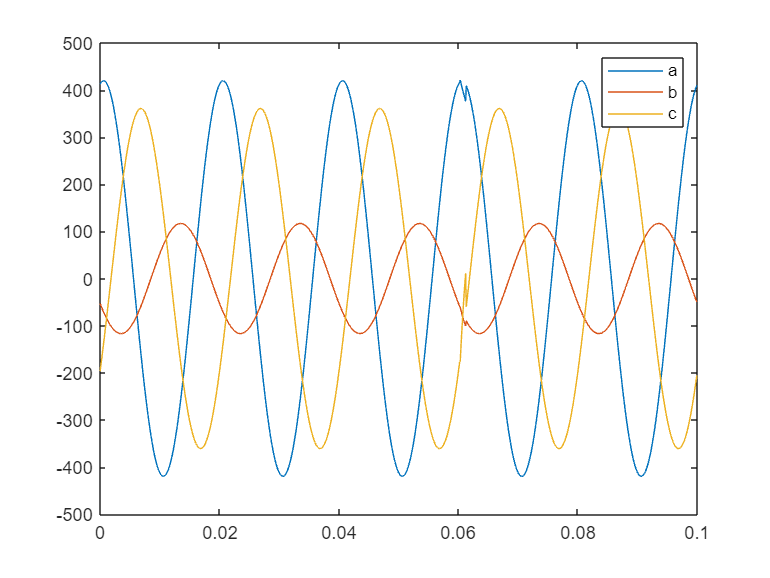

% Use Clarke transform to rotate signal to align (1,1,1) with z-axis
C = (2/3) * [
    1,          -1/2,       -1/2;
    0,          sqrt(3)/2,  -sqrt(3)/2;
    1/sqrt(2),  1/sqrt(2),  1/sqrt(2)
];

signal = C * signal_o;

% Rotated signal components
p1 = signal(1, :);
p2 = signal(2, :);
p3 = signal(3, :); % The zero-sequence

figure; plot(t,p1); hold on; plot(t,p2); plot(t,p3); hold off; legend("a","b","c")

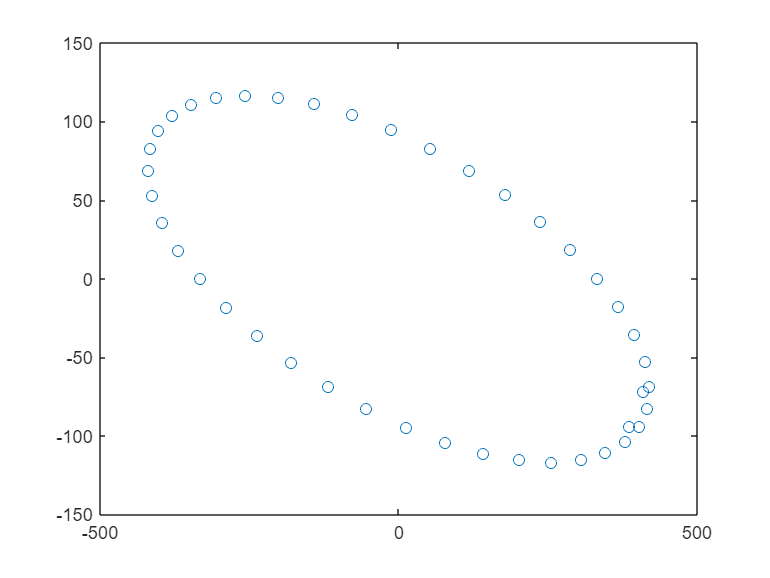

% Now we can take first 2 rotated signal components and try finding the best-fit ellipse
total_points = [p1; p2];

% We probably should down-sample the signal here, we don't practically need all these samples
points = total_points(:, 1:5:nt);
np = size(points, 2);

% Plot points
figure; plot(points(1,:), points(2,:), "Marker","o", "LineStyle","none");

[centerX, centerY, majorTheta, majorLength, minorLength] = fitEllipseGAC(points)

centerX = -0.0105

centerY = 0.0107

majorTheta = -0.1764

majorLength = 425.6714

minorLength = 91.2177

### Draw final results

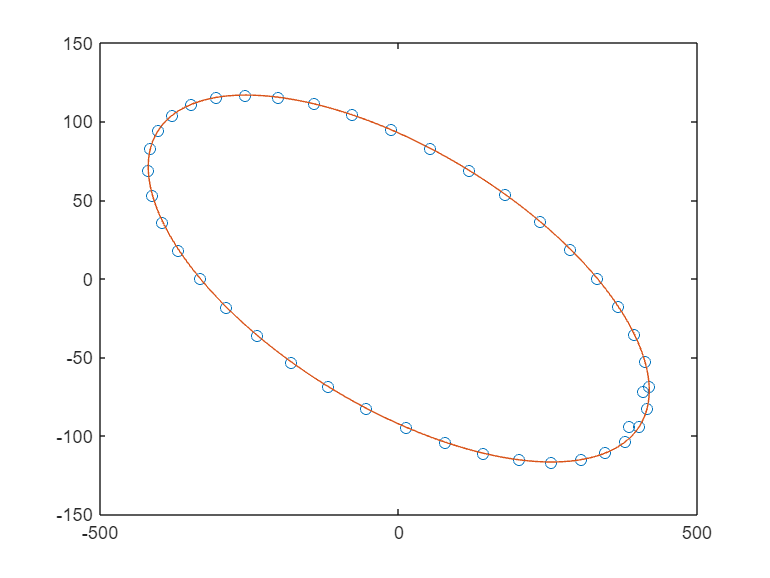

% Ellipse points
ellipsePoints = getEllipsePoints(majorLength, minorLength, majorTheta, centerX, centerY, 361);

% Plot points
plot(points(1,:), points(2,:), "Marker","o", "LineStyle","none");
hold on;
plot(ellipsePoints(1,:), ellipsePoints(2,:), "LineStyle","-");
hold off;

### Extract classification information from ellipse parameters

% Todo: Put sag\swell computations here
% You can use ref "Space Vector Method for Voltage Dips and Swells Analysis"
% Elipse parameters
[Index, curvature] = ElipseCharacterization(majorLength, minorLength, ellipsePoints);

Index

Index =     0.2143
    0.4737
  415.7829
    0.9768
    4.5581
    1.3548
    0.7857
   19.5472


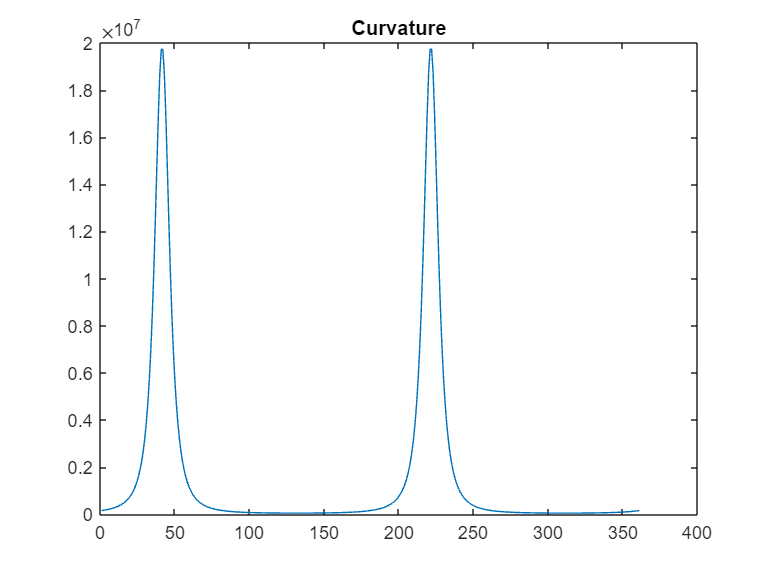

% Plot curvature
figure; plot(1:length(curvature), curvature); title("Curvature")

### Local Optimization Algorithm

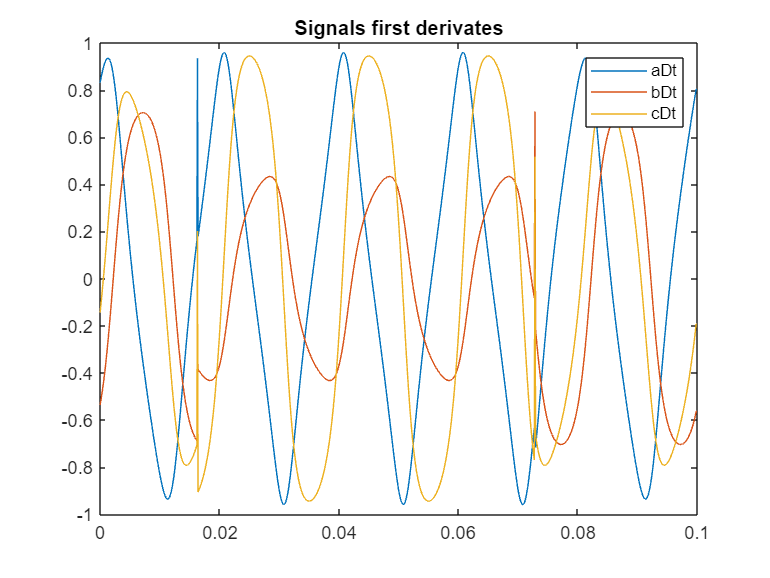

signalDt = [aDt; bDt; cDt];
sDt = sqrt(sum(signalDt .* signalDt, 1));
signalDs = signalDt ./ repmat(sDt, [3, 1]);

figure; plot(t,signalDs(1,:)); hold on; plot(t,signalDs(2,:)); plot(t,signalDs(3,:)); hold off; title("Signals first derivates"); legend("aDt","bDt","cDt");

majorThetaSamples = zeros(1,nt);
majorLengthSamples = zeros(1,nt);
minorLengthSamples = zeros(1,nt);
shapeIndexSamples = zeros(1,nt);
ellipsePointsSamples = zeros(2,361,nt);

% take a number of samples equal to 1/4 of a cycle
k = round(fs/4); 

nk = (k - 1) / 2;

figure;
for s = 1:(nt - k)
    signalPart = signal_o(:, s:(s + k - 1));
    signalDsPart = signalDs(:, s:(s + k - 1));

    % Use Clarke transform to rotate signal to align (1,1,1) with z-axis
    C = (2/3) * [
        1,          -1/2,       -1/2;
        0,          sqrt(3)/2,  -sqrt(3)/2;
        1/sqrt(2),  1/sqrt(2),  1/sqrt(2)
    ];
    
    signalPart = C * signalPart;    
    p1 = signalPart(1, :);
    p2 = signalPart(2, :);
    p3 = signalPart(3, :);

    % plot(p1(1:k)); hold on; plot(p2(1:k)); plot(p3(1:k)); hold off;

    % Now we can take first 2 projected signal components and try finding the best-fit ellipse
    points = [p1, -p1; p2, -p2];
    
    % We could down-sample the signal here, we don't practically need all these samples
    %points = points(:, 1:10:k);
        
    % Plot points
    %plot(points(1,:), points(2,:), "Marker","o", "LineStyle","none");

    % Fit ellipse to points
    [centerX, centerY, majorTheta, majorLength, minorLength] = fitEllipseGAC(points);
    
    majorThetaSamples(s) = majorTheta;
    majorLengthSamples(s) = majorLength;
    minorLengthSamples(s) = minorLength;
    shapeIndexSamples(s) = minorLength / majorLength;

    %Plot points and ellipse
    ellipsePointsSamples(:,:,s) = getEllipsePoints(majorLength, minorLength, majorTheta, centerX, centerY, 361);
    % 
    % plot(points(1,:), points(2,:), "Marker","o", "LineStyle","none");
    % hold on;
    % plot(ellipsePoints(1,:), ellipsePoints(2,:), "LineStyle","-");
    % hold off;
end

[mean(majorThetaSamples) * 180 / pi;
mean(majorLengthSamples);
mean(minorLengthSamples);
mean(shapeIndexSamples)]

ans = 1.0e+02 *

   0.2942 + 0.0000i
   4.0379 + 1.1055i
   3.1604 + 0.0000i
   0.0060 - 0.0005i


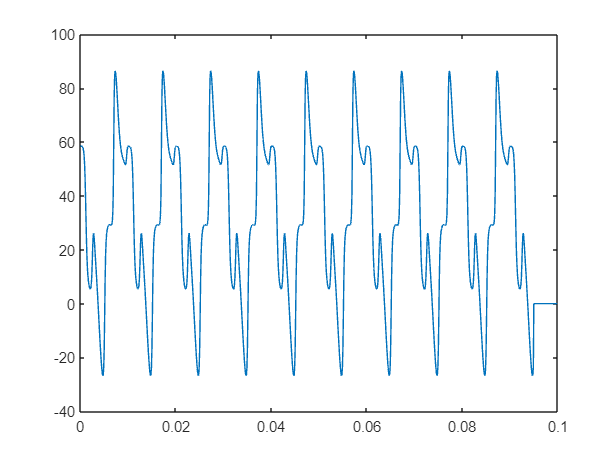


plot(t, majorThetaSamples*180/pi)

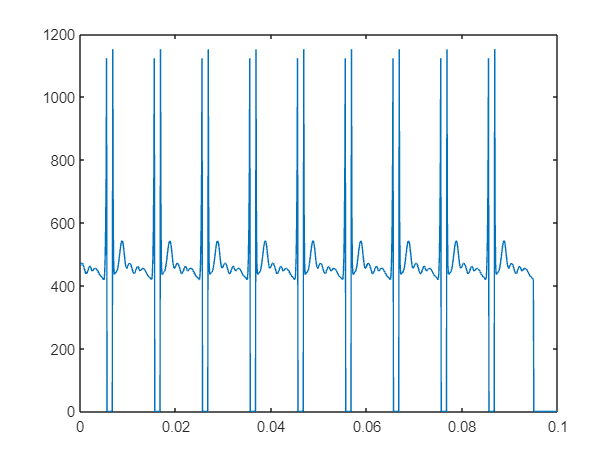

plot(t, majorLengthSamples);

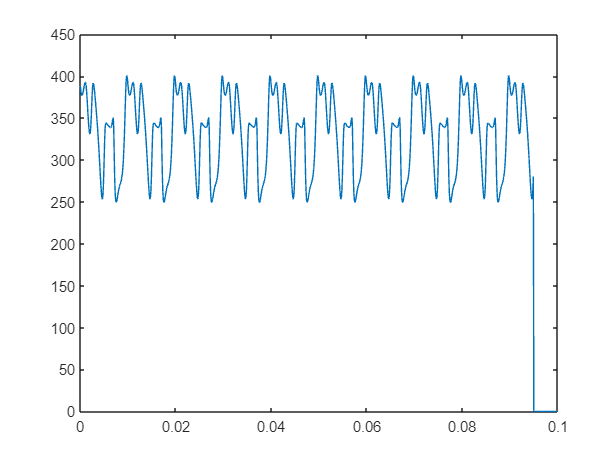

plot(t, minorLengthSamples);

[index, curvature] = ElipseCharacterization(majorLengthSamples, minorLengthSamples, ellipsePointsSamples);

figure
plot(t,index(1,:));

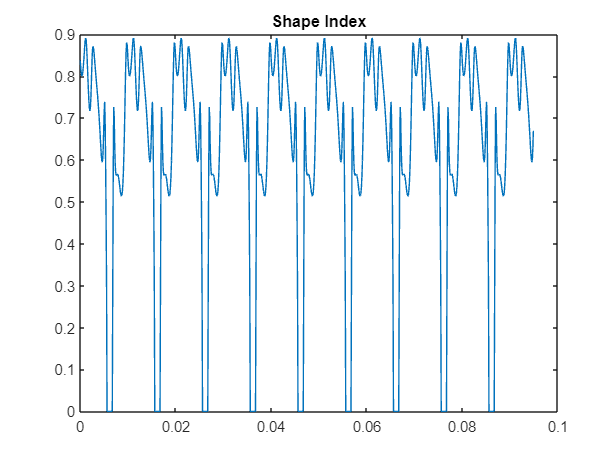

title("Shape Index")

figure
plot(t,index(2,:));

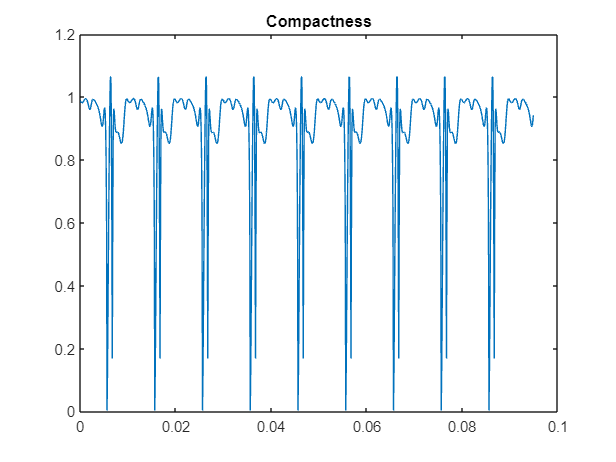

title("Compactness")

figure
plot(t,index(3,:));

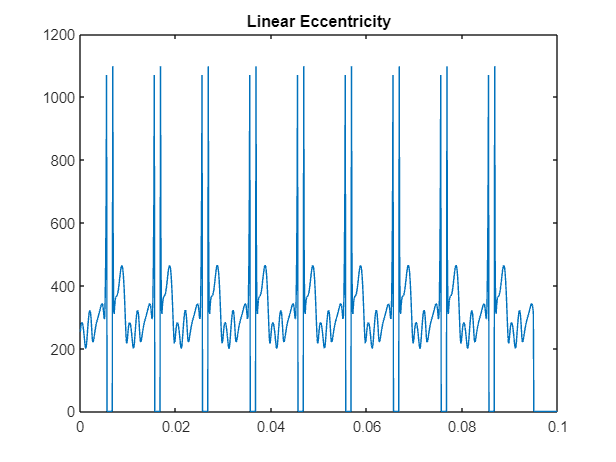

title("Linear Eccentricity")

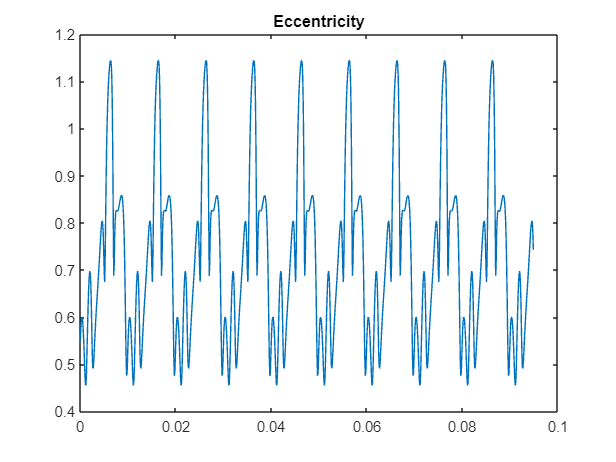

figure
plot(t,index(4,:));
title("Eccentricity")

figure
plot(t,index(5,:));

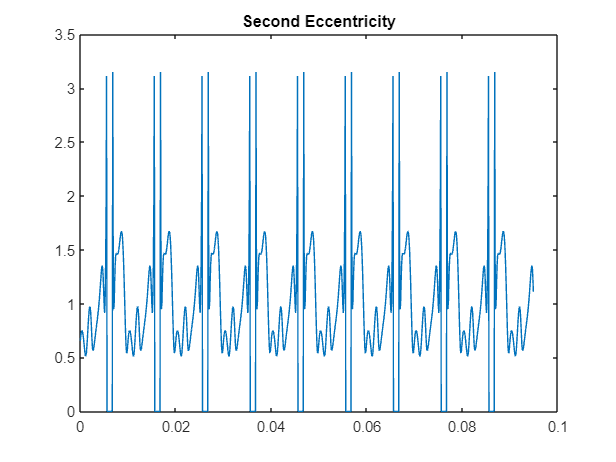

title("Second Eccentricity")

figure
plot(t,index(6,:));

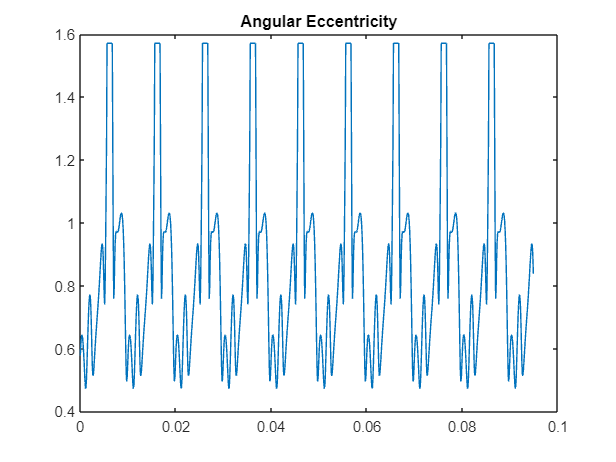

title("Angular Eccentricity")

figure
plot(t,index(7,:));

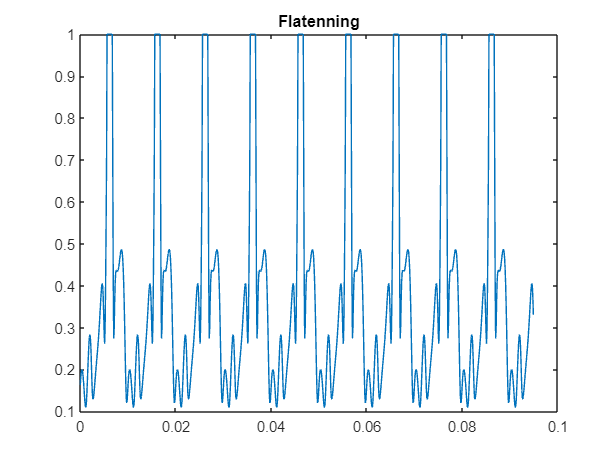

title("Flatenning")

figure
plot(t,index(8,:));

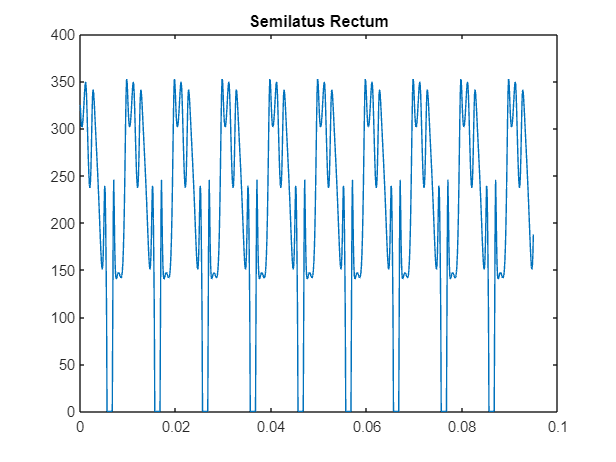

title("Semilatus Rectum")

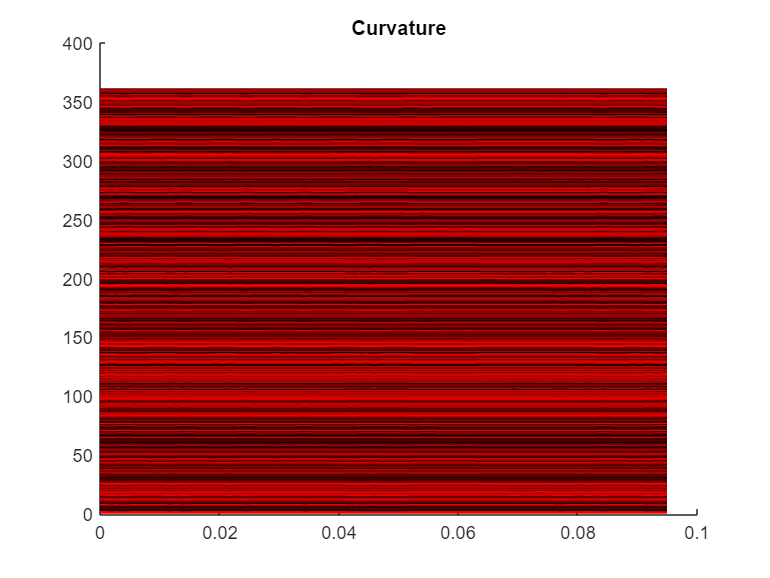

figure()
hold on

for n=1:length(curvature(:,1))
plot3(t, n*ones(1,length(t)), curvature(n,:), "Color", [rand(1),0,0])
end
legend("t","s","c")
title("Curvature")